# Math 9 Final Project: SIR Model for Disease Spread

*Cyrus Young*

*I hereby confirm that the present report is my own work. If any texts or codes from books, papers,*

*the Web, or any other sources have been copied or in any other way used, all references have been*

*acknowledged and cited. I am aware that the instructor has the authority to report and investigate*

*any potential academic misconduct in this course, and such misconduct could lead to failing this*

*course. If I have employed any AI models (including but not limited to ChatGPT), I have*

*appropriately and explicitly acknowledged their use in the report whenever the results were*

*generated with the aid of AI.*

## What is a Mathematical Model?

On its own, mathematics isn't very "useful" to people. What ultimately makes math important is its ability to be used to interpret physical or real world phenomena. So, one can define a "mathematical model" as "a collection of mathematical tools, definitions, and notations used to interpret a real world phenomenon". Examples of mathematical models are everywhere. Newtonian physics primarily uses "real analysis" and "linear algebra" to interpret the movement of physical objects. One can gain an understanding of the frequency/likelyhood of specific events, or the popularity of certain opinions/beliefs, by using what is broadly known as "statistics". Object oriented computer science languages are a bit of a special case, in that it's almost a literal interpretation of linear algebra and finitary mathematical logic / set theory. In the case of studying infectious diseases, one can use dynamical systems, stochastic processes, and computer science, to interpret the rate at which a disease spreads within a community, or keep track of the effectiveness of a cure to a disease.

## The Susceptible-Infectious-Recovered (SIR) Model

We denote:

*N* = total number of people within the population (constant).

𝑆(𝑡) = proportion of *susceptibles* at time 𝑡.

𝐼(𝑡) = proportion of *infectives* at time 𝑡.

𝑅(𝑡) = proportion of *recovered/removed* at time *t.*

$\beta$ = rate of infection when contacting a patient.

$\gamma$ = rate of recovery.

The standard SIR model is the following collection of ordinary differential equations:

**1)    **$\frac{\mathrm{d}}{\mathrm{d}t}S\left(t\right)=-\frac{\beta }{N}I\left(t\right)S\left(t\right)$    

- More people become susceptible if many people are infected or already susceptible

**2)    **$\frac{\mathrm{d}}{\mathrm{d}t}R\left(t\right)=\gamma I\left(t\right)\;$

- More people recover if many people are infected.

**3)    **$\frac{\mathrm{d}}{\mathrm{d}t}I\left(t\right)=\frac{\beta }{N}I\left(t\right)S\left(t\right)-\gamma I\left(t\right)$,        or        $\frac{\mathrm{d}}{\mathrm{d}t}S\left(t\right)+\frac{\mathrm{d}}{\mathrm{d}t}I\left(t\right)+\frac{\mathrm{d}}{\mathrm{d}t}R\left(t\right)=0$

- The number of infected depends entirely on **1) **and 2**)**.

- The number of people being studied within the population at any time *t *is constant, equal to *N*.

**Basic Reproduction Number**

The *basic reproduction number *$R_0$ is defined by $R_0 =\frac{\beta }{\gamma }$. This can be interpreted as the number of new infected people infected by a single person who is already infected, given that everybody within the population is susceptible. if $R_0 >1$, then essentially, everybody is infecting at least one person, and the infection is spreading rapidly. In [1], the authors state that during the early months of COVID (February-April 2023), the basic reproduction number across Europe was about 4.5.

## Example Scenario

People in a small town (total population: 10000) are experiencing the flu season, and today's record shows that 10 people have already recovered, and 200 people are having the flu. Assume that active immunity is obtained once fully recovered, and the newborn and death can be neglected during a short period of time. We will run two trials; in the first we assume that the rate of infection when contacting a patient is 75%, and every day a patient has a probability of 15% of becoming fully recovered (rate of recovery). In the second, the rate of infection is 0.45, and the rate of recovery is 0.25


$$N=10000$$



$$S\left(0\right)=9780$$



$$I\left(0\right)=200$$



$$R\left(0\right)=10$$



$$\beta =0\ldotp 75,\;\;\;0\ldotp 45$$



$$\gamma =0\ldotp 15,\;\;\;0\ldotp 25$$
 

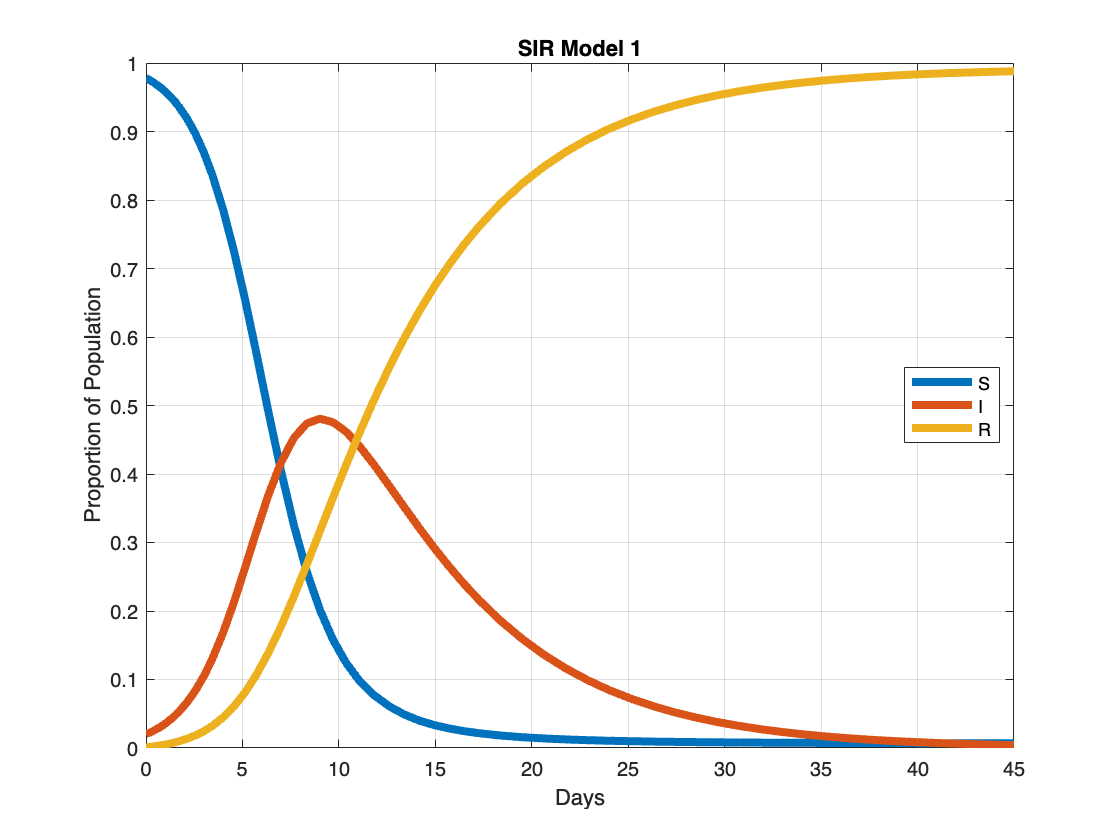

clearvars
N = 10000;
S_init = 9780;
I_init = 200;
R_init = 10;
days = 45;
beta = 0.75;
gamma = 0.15;

[t, y] = ode45(@(t, y) simple_SIR(t, y, beta, gamma), [0 days], [S_init, I_init, R_init]./N);
S = y(:, 1);
I = y(:, 2);
R = y(:, 3);



% first SIR model
plot(t, S, 'LineWidth', 4, 'DisplayName', 'S');
hold on;
plot(t, I, 'LineWidth', 4, 'DisplayName', 'I');
plot(t, R, 'LineWidth', 4, 'DisplayName', 'R');
xlabel('Days');
ylabel('Proportion of Population');
title('SIR Model 1');
legend('Location', 'best');
grid on;
hold off;

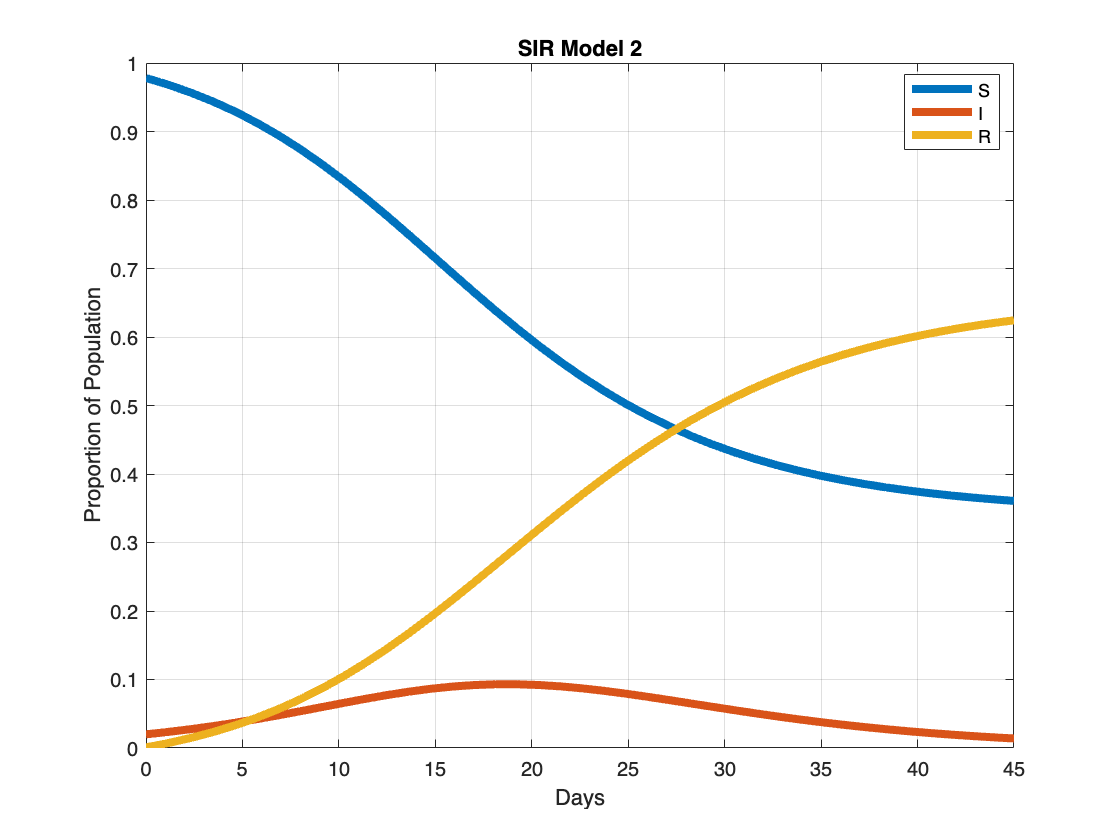

beta_2 = 0.4;
gamma_2 = 0.25;

[t, y] = ode45(@(t, y) simple_SIR(t, y, beta_2, gamma_2), [0 days], [S_init, I_init, R_init]./N);

S = y(:, 1);
I = y(:, 2);
R = y(:, 3);

% second SIR model
plot(t, S, 'LineWidth', 4, 'DisplayName', 'S');
hold on;
plot(t, I, 'LineWidth', 4, 'DisplayName', 'I');
plot(t, R, 'LineWidth', 4, 'DisplayName', 'R');
xlabel('Days');
ylabel('Proportion of Population');
title('SIR Model 2');
legend('Location', 'best');
grid on;
hold off;

## Example Scenario Cont. (Random Infection and Recovery)

We repeat the previous scenario, except we run 20 separate simulations, each with a random infection rate between 30% and 90%, and a random recovery rate between 10% and 30%.

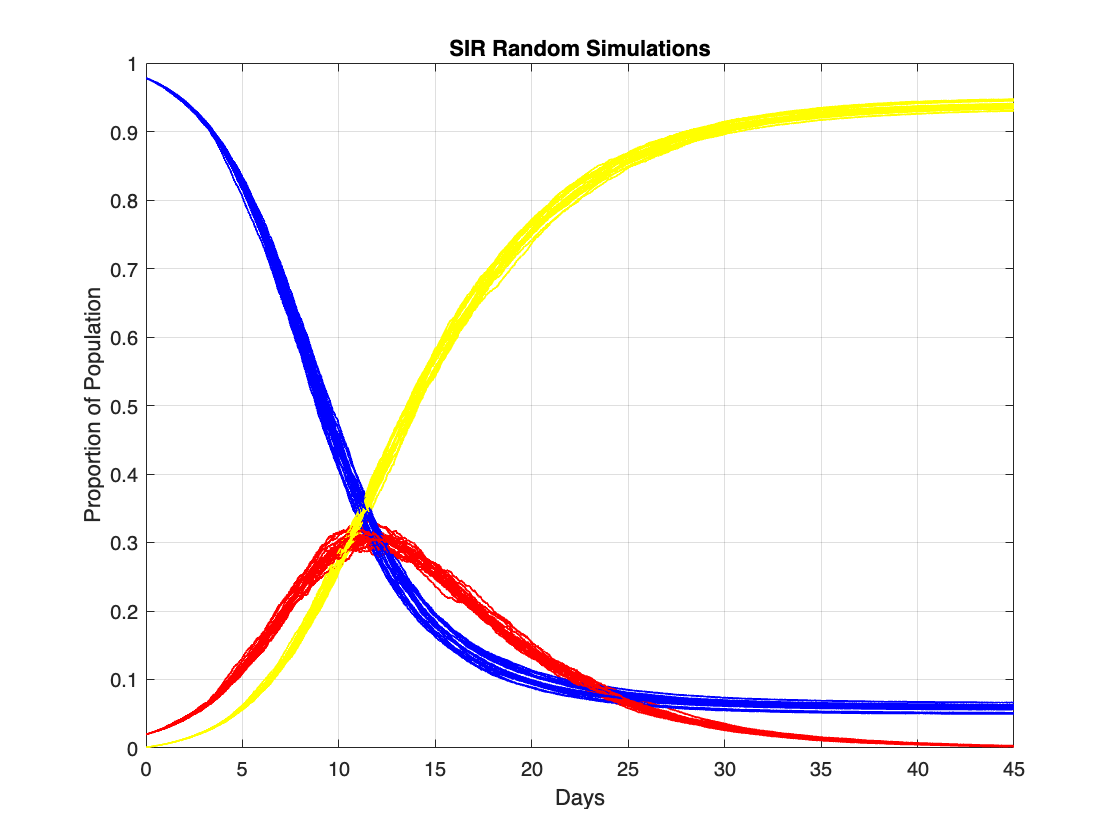

clearvars
N = 10000;
S_init = 9780;
I_init = 200;
R_init = 10;
days = 45;


% 20 simulations
for i = 1:20
    [t, y] = ode45(@(t, y) simple_SIR_2(t, y), [0 days], [S_init, I_init, R_init]./N);

    S = y(:, 1);
    I = y(:, 2);
    R = y(:, 3);
 
    plot(t, S, 'LineWidth', 1, 'Color', 'Blue');
    hold on;
    plot(t, I, 'LineWidth', 1, 'Color', 'Red');
    hold on;
    plot(t, R, 'LineWidth', 1, 'Color', 'Yellow');
end

xlabel('Days');
ylabel('Proportion of Population');
title('SIR Random Simulations');
grid on;
hold off;

Even when accounting for randomness of the rate of infection and the rate of recovery, each simulation more or less follows the same general trend. Around day 12, about one third of the populations were in each of the three categories for each simulation. By the end of each simualtion, almost all of the infected had recovered, and a small portion of the population stayed susceptible to the virus.

## Hong Kong Flu in New York City

We now analyze the spread of the 1968 Flu pandemic in New York City, which had a population of approximately 7,900,000 people that year. We have the following data from [2]:

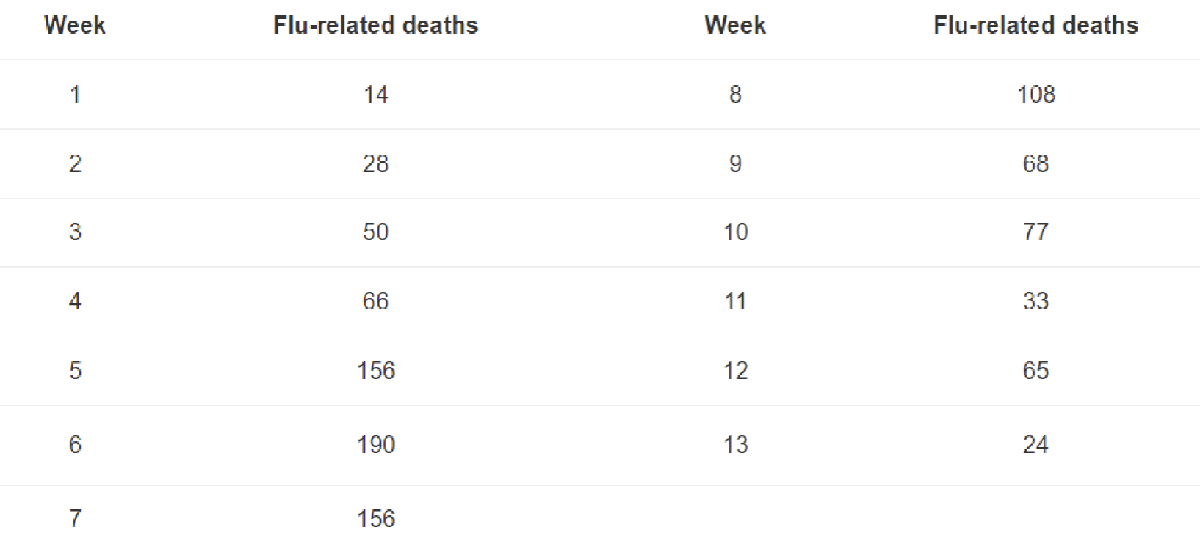

It is estimated that the number of weekly deaths is approximately 1/500 of the number of weekly infected. We assume the following initial conditions:


$$N=7,900,000$$



$$S\left(0\right)=7,893,000$$



$$I\left(0\right)=7,000$$



$$R\left(0\right)=0$$


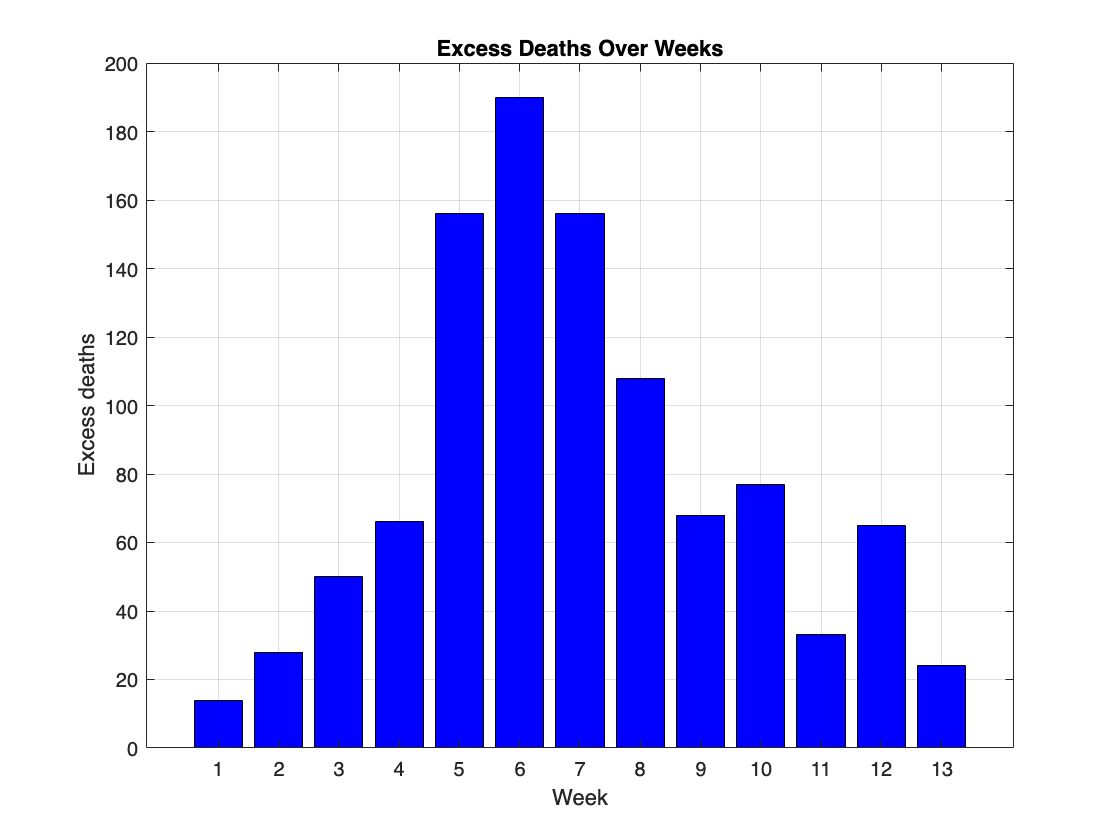

clearvars

data = [14, 28, 50, 66, 156, 190, 156, 108, 68, 77, 33, 65, 24];

%barplot
bar(1:13, data, 'b');
xlabel('Week');
ylabel('Excess deaths');
title('Excess Deaths Over Weeks');
grid on;
hold off;

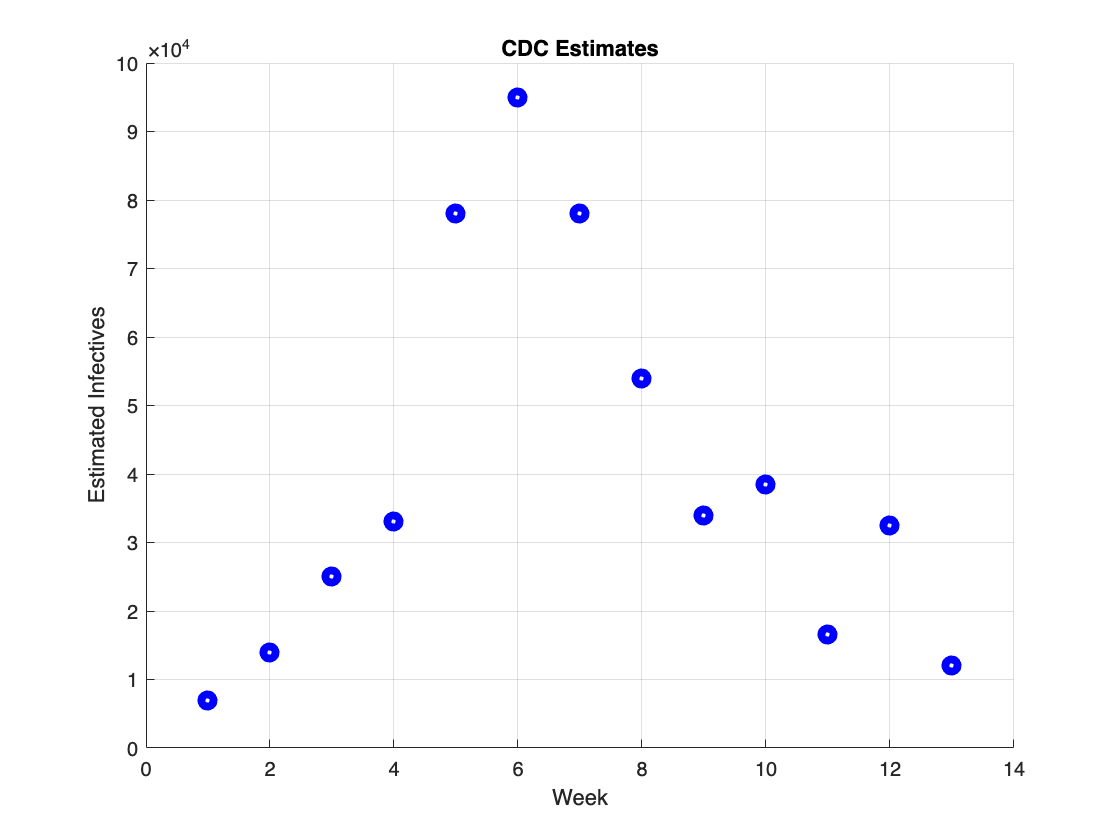

% 2.

N = 7900000;
I_init = 14*500;
S_init = N - I_init;
R_init = 0;
beta = 0.5;
gamma = 0.6;
days = 100;

[t, y] = ode45(@(t, y) simple_SIR(t, y, beta, gamma), [0 days], [S_init, I_init, R_init]./N);
S = y(:, 1);
I = y(:, 2);
R = y(:, 3);

%scatter plot
scatter(1:13, data*500, 'b', 'LineWidth', 4)
xlabel('Week');
ylabel('Estimated Infectives');
title('CDC Estimates');
grid on;
hold off;

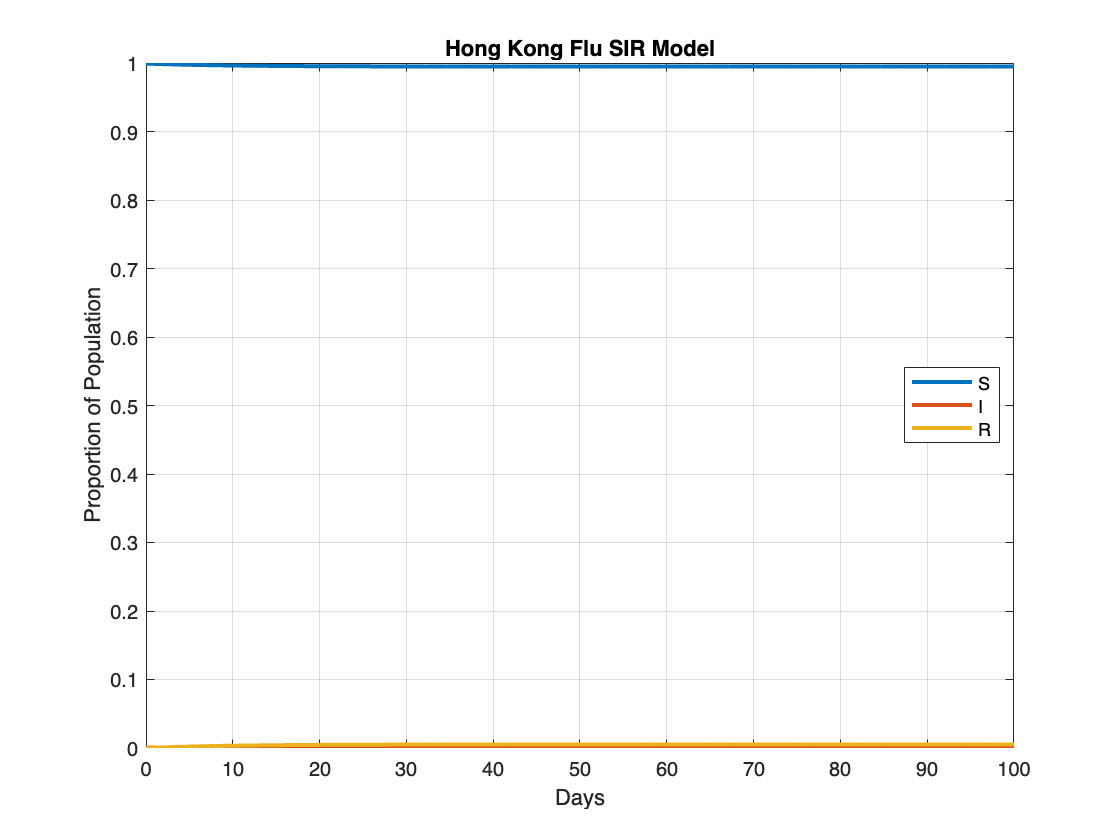

% 3.

%SIR plot for Hong Kong flu data
plot(t, S, 'LineWidth', 2, 'DisplayName', 'S');
hold on;
plot(t, I, 'LineWidth', 2, 'DisplayName', 'I');
plot(t, R, 'LineWidth', 2, 'DisplayName', 'R');
xlabel('Days');
ylabel('Proportion of Population');
title('Hong Kong Flu SIR Model');
legend('Location', 'best');
grid on;
hold off;

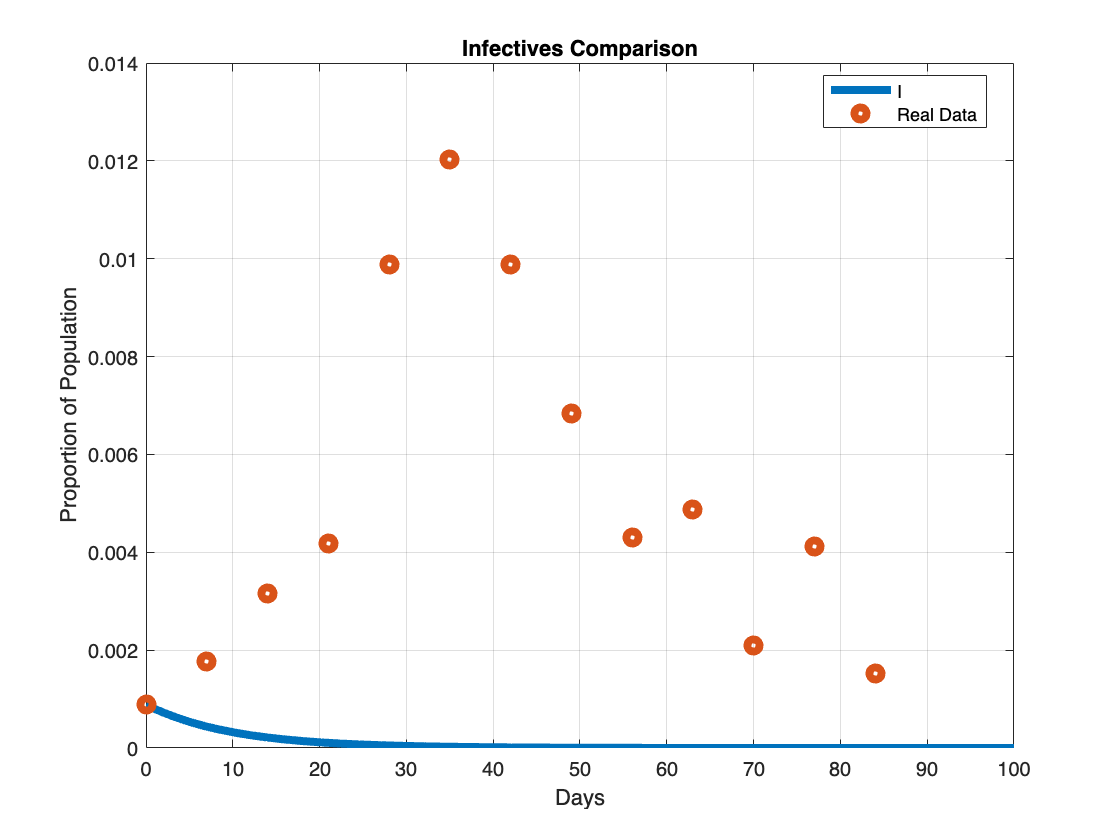

% 4.

%comparison plot
plot(t, I, 'LineWidth', 4, 'DisplayName', 'I');
hold on;
scatter(0:7:84, data*(500/N), 'DisplayName', 'Real Data', 'LineWidth', 4)
xlabel('Days');
ylabel('Proportion of Population');
title('Infectives Comparison');
legend('Location', 'best');
grid on;
hold off;

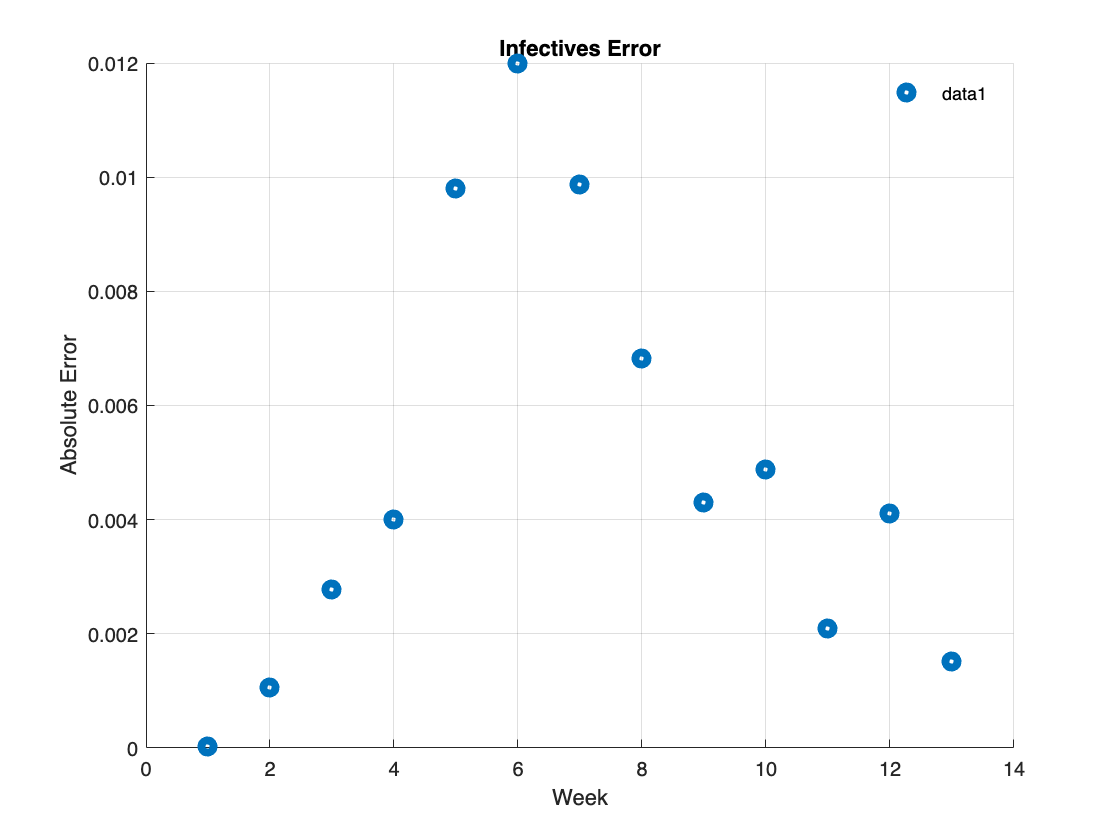

%absolute error
fitting_err = zeros(1,13);
for i = 1:13
    fitting_err(1, i) = abs(data(i)*(500/N) - I(4*i+1));
end
scatter(1:13, fitting_err, 'LineWidth', 4)
xlabel('Week');
ylabel('Absolute Error');
title('Infectives Error');
legend('boxoff')
grid on;

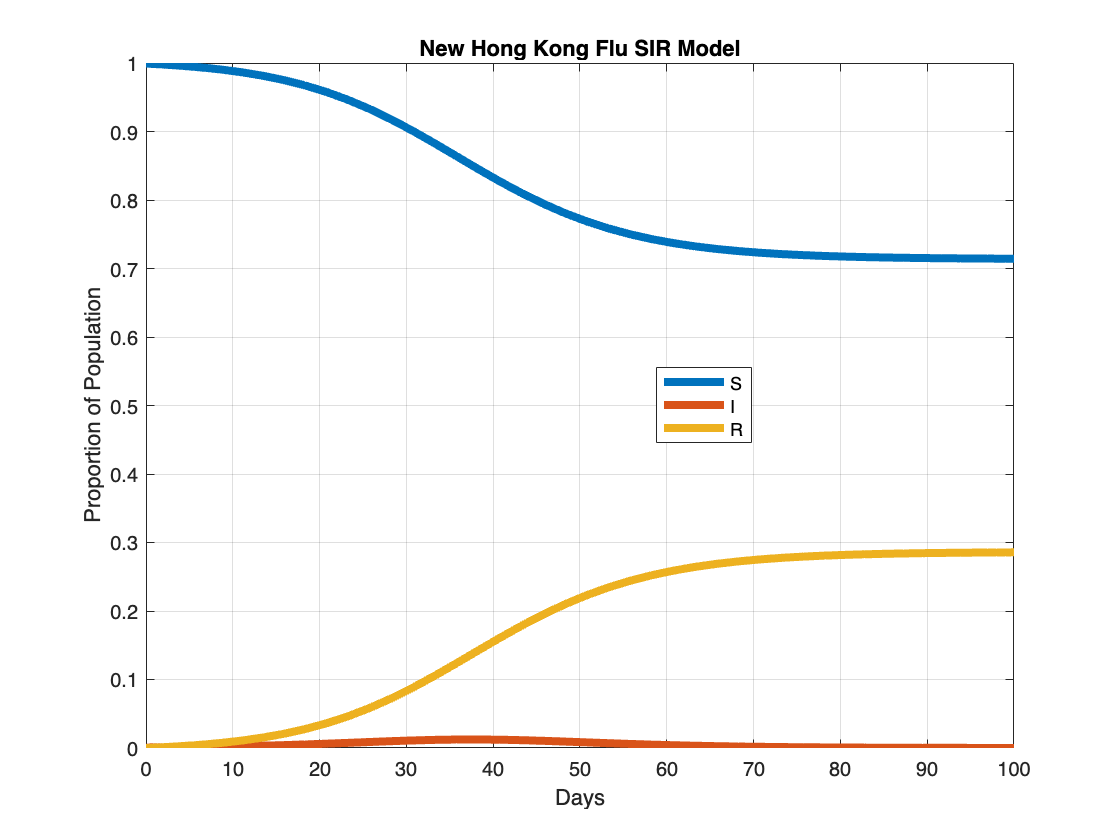

% 5. 

beta = 0.705;

[t, y] = ode45(@(t, y) simple_SIR(t, y, beta, gamma), [0 days], [S_init, I_init, R_init]./N);
S = y(:, 1);
I = y(:, 2);
R = y(:, 3);

%new SIR plot Hong Kong Flu data
plot(t, S, 'LineWidth', 4, 'DisplayName', 'S');
hold on;
plot(t, I, 'LineWidth', 4, 'DisplayName', 'I');
plot(t, R, 'LineWidth', 4, 'DisplayName', 'R');
xlabel('Days');
ylabel('Proportion of Population');
title('New Hong Kong Flu SIR Model');
legend('Location', 'best');
grid on;
hold off;

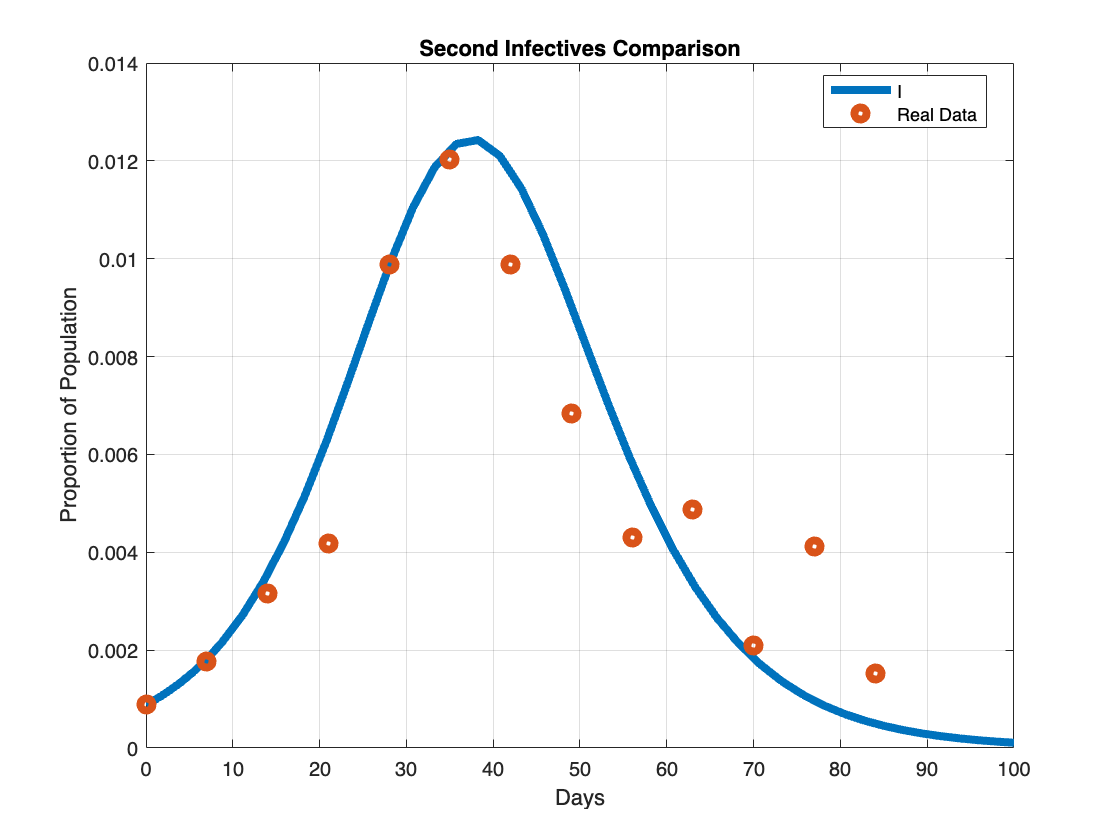

%second infectives comparison
plot(t, I, 'LineWidth', 4, 'DisplayName', 'I');
hold on;
scatter(0:7:84, data*(500/N), 'DisplayName', 'Real Data', 'LineWidth', 4)
xlabel('Days');
ylabel('Proportion of Population');
title('Second Infectives Comparison');
legend('Location', 'best');
grid on;
hold off;

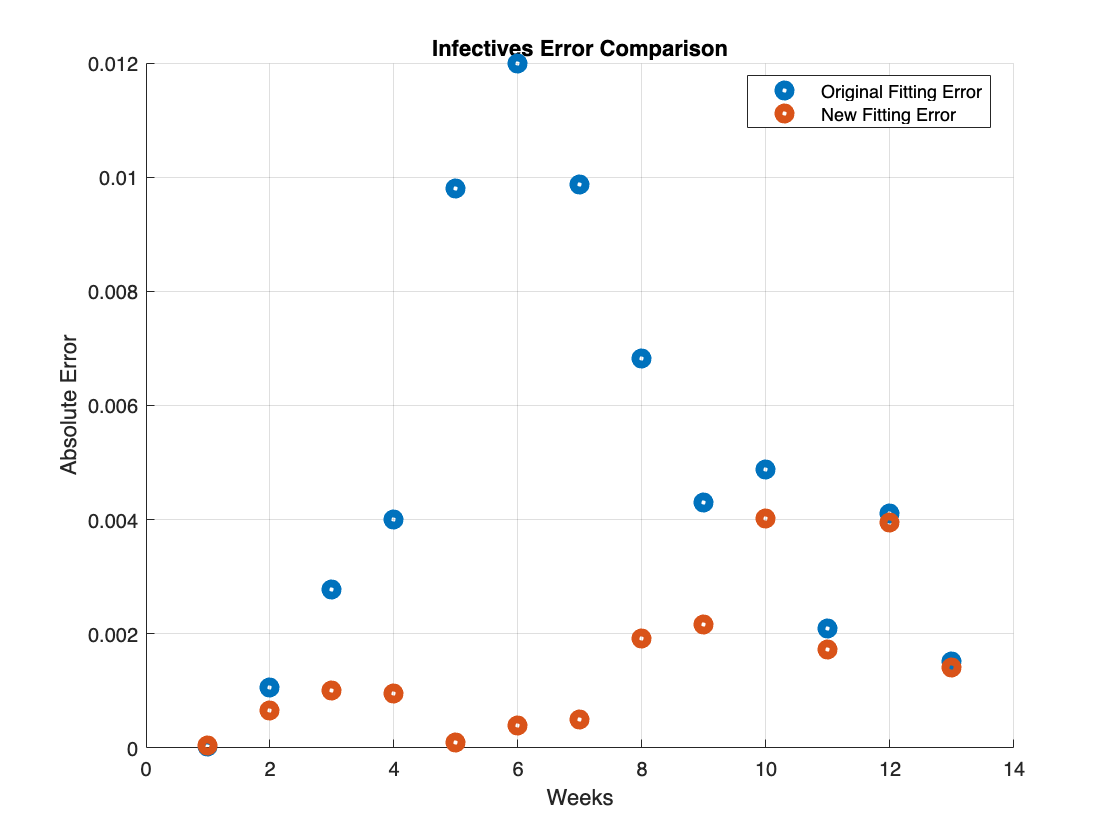

%compare fitting errors
fitting_err_2 = zeros(1,13);

for i = 1:13
    fitting_err_2(1, i) = abs(data(i)*(500/N) - I(4*i+1));
end

scatter(1:13, fitting_err(1:13), 'LineWidth', 4, 'DisplayName', 'Original Fitting Error');
hold on;
scatter(1:13, fitting_err_2, 'LineWidth', 4, 'DisplayName', 'New Fitting Error');
xlabel('Weeks');
ylabel('Absolute Error');
title('Infectives Error Comparison');
legend('Location', 'best');
grid on;
hold off;

With these two trials, we can observe that a good value for the infection rate is 0.705, and a good value for the recovery rate to be 0.6.

## **Analysis**

From the work done in this project, I've learned that the SIR model is reasonably effective at predicting the spread of a virus within a given population. I found it interesting how, after obtaining enough tata to make calculations, finding the right curve to describe the data boiled down to obtaining only the rate of infection and the rate of recovery. There are a few limitations to this model:

- For large populations, this model might not be very useful. One would likely have to break up a large population into smaller groups for the SIR model to be effective. For example, If the entire US was being studied during the COVID outbreak, SIR would be more useful For evaluating each county within a state.

- SIR does not seem to account for multiple outbreaks. I remember distinctly that COVID had peaks multiple different times. It's possible that this could be fixed by having a different SIR model for each peak.

- Partially discussed in Task 4, in many cases it's unlikely that the rate of recovery and the rate of infection are constant. Either this cound be accounted for using randomness, or a more well defined function over time can be defined for each of the rates.

## **References**

[1] 

Katul GG, Mrad A, Bonetti S, Manoli G, Parolari AJ. Global convergence of COVID-19 basic reproduction number and estimation from early-time SIR dynamics. PLoS One. 2020 Sep 24;15(9):e0239800. doi: 10.1371/journal.pone.0239800. PMID: 32970786; PMCID: PMC7514051.

[2]

“Ode45.” *MATLAB*, [www.mathworks.com/help/matlab/ref/ode45.html.](http://www.mathworks.com/help/matlab/ref/ode45.html.)

[3]

D. Smith and L. Moore, The SIR model for spread of disease - background: Hong Kong flu, J. Online Math. Appl., Dec. (2004).

## Functions

function dydt = simple_SIR(t, y, beta, gamma)
    dS = -beta * y(1) * y(2) ;
    dI = (beta * y(1) * y(2) - gamma * y(2));
    dR = gamma * y(2);
    dydt = [dS; dI; dR];
end

function dydt = simple_SIR_2(t, y)
    K = rand;
    L = rand;
    dydt = simple_SIR(t, y, 0.3 + (0.6 * K), 0.1 + (0.2 * L));
end